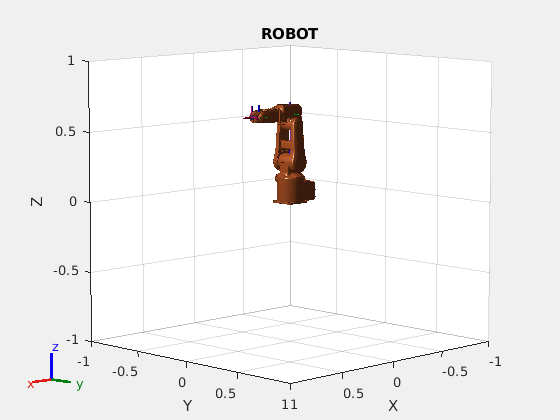

robo = loadrobot('abbIrb120');
ax = show(robo);
title(ax,'ROBOT');
hold('on');

pts = readtable('DataScience/project/archive/robot_inverse_kinematics_dataset.csv');
pts

pts = 15000×9 table
      q1         q2       q3       q4        q5       q6         x           y         z  
    _______    ______    ____    ______    ______    _____    ________    _______    _____

      -1.51    -0.763    1.85    -0.817     0.912     2.32     -0.0947       0.15    0.301
      -2.84      0.52    1.58     -1.27     -1.39    0.617       0.142       -0.1    0.225
      -1.23     0.695    1.22     -1.13    0.0343     6.27     -0.0833      0.223    0.206
      -1.99      1.06    1.74     -1.76     -1.24     4.76       0.135    -0.0314     0.37
       1.05     0.836    1.34     -1.89     0.484     4.38      -0.056     -0.229     0.26
      0.762    -0.717    1.86      1

x = pts(:,7);
y = pts(:,8);
z = pts(:,9);

x_d = table2array(x);
y_d = table2array(y);
z_d = table2array(z);

%plot3(ax,x_d,y_d,z_d)
robo.BodyNames

ans = 1×8 cell array
    {'base'}    {'link_1'}    {'link_2'}    {'link_3'}    {'link_4'}    {'link_5'}    {'link_6'}    {'tool0'}


pos = [x_d(1) y_d(1) z_d(1)];
posvec = trvec2tform(pos);
disp(posvec)

    1.0000         0         0   -0.0947
         0    1.0000         0    0.1500
         0         0    1.0000    0.3010
         0         0         0    1.0000



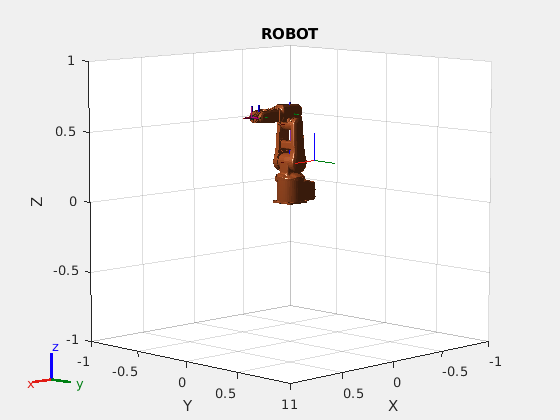

plotTransforms(pos,eul2quat([0 0 0]),FrameSize=0.2);

ik = inverseKinematics("RigidBodyTree",robo);
weights = [0 0 0 1 1 1];
initialguess = homeConfiguration(robo);

[configSoln,solnInfo] = ik("link_6",posvec,weights,initialguess);

configSoln

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


show(robo,configSoln);
pose = getTransform(robo,configSoln,"base","link_6");
pose

pose =    -0.3029    0.2505   -0.9195    0.2105
   -0.9426   -0.2213    0.2502   -0.1314
   -0.1408    0.9425    0.3032   -0.2460
         0         0         0    1.0000


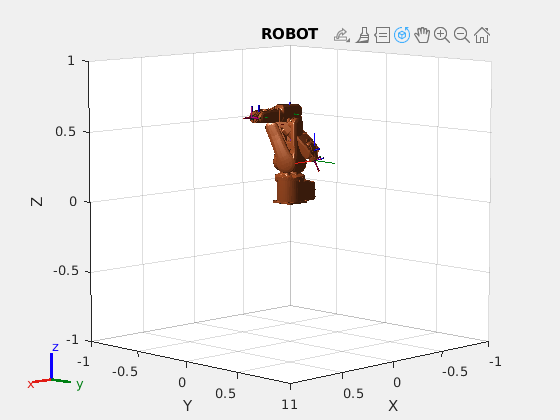

hold('off');

**RANDOM JOINT CONFIGURATION FROM GIVEN DATASET**

hold('off'); 

config = pts(1,1:6);
config = table2array(config);
disp('COnfig: ')

COnfig: 


disp(config);

   -1.5100   -0.7630    1.8500   -0.8170    0.9120    2.3200




home_config = homeConfiguration(robo)

home_config = 1×6 struct array with fields:
    JointName
    JointPosition


for i = 1:6
    home_config(i).JointPosition = config(i);
end
newpose = getTransform(robo,home_config,"base","link_6");
disp(newpose);

   -0.5873    0.1589   -0.7936    0.1298
   -0.0795   -0.9871   -0.1389    0.0192
   -0.8055   -0.0185    0.5923   -0.1478
         0         0         0    1.0000



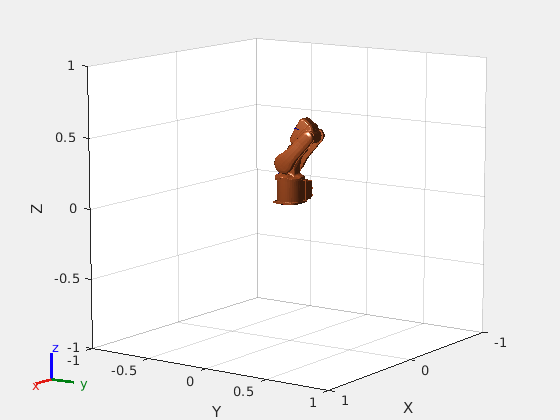

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(robo,home_config) 